%%%%%%%
% Example code to load the data and output the CIE coordinates and sRGB results
% This code was developed to read the hyperspectral transmittance data 
% measured by DIDSR's Hyperspectral Imaging Microscope (HIMS) for a selection 
% of 8 BiomaxOrgan10 tissue microarray slides (US Biomax, 15883 Crabbs Branch Way, MD 20855, USA):
% - Bladder
% - Brain
% - Breast
% - Colon
% - Kidney
% - Liver
% - Lung
% - Uterine Cervix

% input = 
%   - transmittance:                                    39 x (sizey*sizex) array
%   - standard deviation on transmittance:              39 x (sizey*sizex) array
% output = 
%   - CIEXYZ: CIE 1931 tri-stimulus coordinates         (sizey*sizex) x 3 array
%   - CovXYZ: Covariance matrix on XYZ coordinates      3 x 3 x (sizey*sizex) array
%   - CIELAB: CIELab 1976 coordinates                   (sizey*sizex) x 3 array
%   - CovLAB: Covriance matrix on Lab coordinates       3 x 3 x (sizey*sizex) array
%   - rgb: sRGB                                         (sizey*sizex) x 3 array

clearvars;
close all;

## Load data

Path to BiomaxOrgan 10 data

biomax_path = pwd;

% Name of the sample
% sample_name = 'UterineCervix_red';
sample_name = 'BiomaxOrgan10_UterineCervix_B10';

% Create ReadSpectralDataBase Object
dt = ReadSpectralDatabase(biomax_path, sample_name);

## Define Standard illuminant

d65 = LightSource([pwd '\input\DataIlluminants\spec_cied65']);
dt.set_ls(d65.ls);

## Compute CIEXYZ coordinates

dt.transmittance2XYZ('y') % 'y' to trim the transmittance to 1. The measured transmittance can be > 1 due to measurement uncertainties.

## Compute CIELAB coordinates

dt.transmittance2LAB('y') % 'y' to trim the transmittance to 1

## Compute sRGB values

dt.transmittance2sRGB ('y') % 'y' to trim the transmittance to 1

## Display results

pix_pos = [266 52; 337 266; 416 319];
pix_label = {'Superficial cells', 'Basal cells', 'Stroma'}; % Labels for UterineCervix_red only
dt.displ_res(pix_pos);

## Points of interest from Jocelyn

%{
Bladder:
[683 261] (superficial umbrella cells)
[621 271] (intermediate urothelial cells)
[325 372] (connective tissue)
[451 326] (basal urothelial cells)

Uterine Cervix:
[266 52] (superficial cells)
[559 184] (intermediate cells)
[337 266] (basal cells)
[416 319] (stroma)

Brain:
[484 498] (blood vessel, RBC's)
[364 376] (neuron)
[452 357] (neuropil)

Breast:
[360 433] (connective tissue)
[142 211] (epithelial cells)

Colon:
[762 618] (RBC's)
[763 477] (muscularis mucosa)
[598 545] (epithelial cells, glandular)
[338 177] (laminar propria)

Kidney:
[250 594] (RBC's)
[203 344] (tubule, cytoplasm)
[256, 491] (glomerulus, nucleus)
[371 431] (glomerulus, cytoplasm)
[196 337] (tubule, nucleus)

Liver:
[577 477] (hepatocyte, nucleus)
[599 446] (hepatocyte, cytoplasm)

Lung:
[673 537] (blood vessel, RBC's)
[467 401] (alveolar walls, cytoplasm)
[590 406] (alveolar walls, nuclei)
%}

## Reshape sRGB to tiff and display truth image

disp('Showing sRGB image');

Showing sRGB image


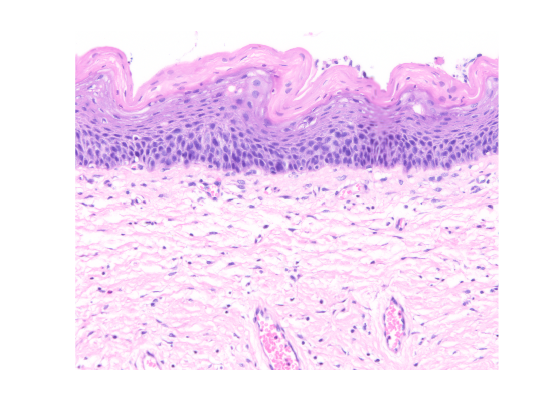

im = reshape(dt.rgb, dt.sizey, dt.sizex,3); %im: sizey x sizex x 3 array
figure;
image(im);
axis image;
axis off

## Plots

disp('Showing transmittance plots');

Showing transmittance plots


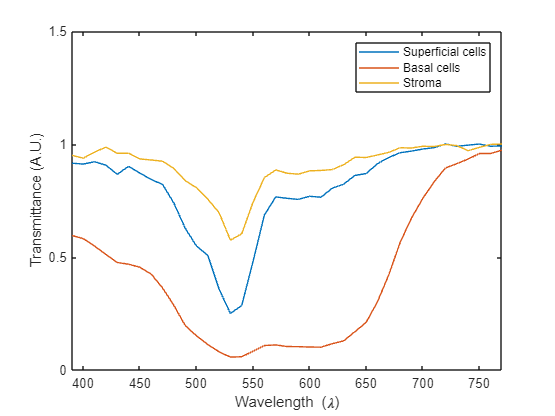


% Plot of transittance data
dt.plot_t_spectra(pix_pos, 'colororder'); % The color option can be 'rgb' or 'colororder'
legend(pix_label);

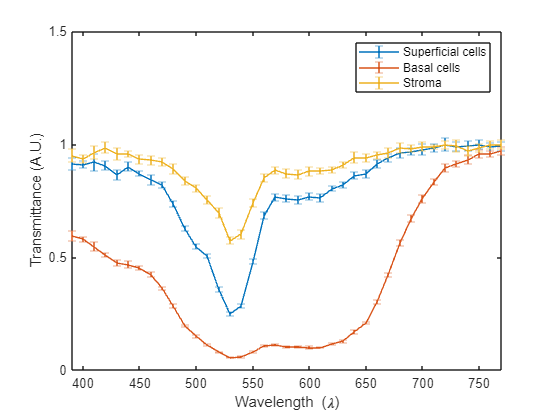


% Errorbar of transmittance data
dt.errorbar_t_spectra(pix_pos, 'colororder'); % The color option can be 'rgb' or 'colororder'
legend(pix_label);


% LAB
disp('Showing scatter3 CIELAB');

Showing scatter3 CIELAB


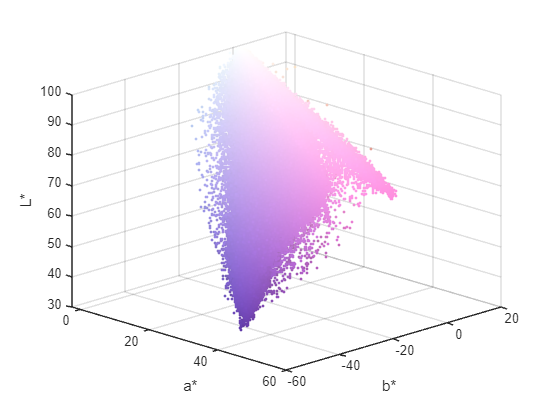

dt.scatter3('LAB');


% XYZ
disp('Showing scatter3 CIEXYZ');

Showing scatter3 CIEXYZ


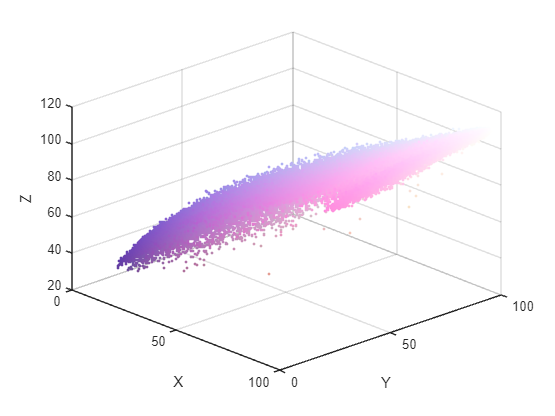

dt.scatter3('XYZ');


% sRGB
disp('Showing scatter3 sRGB');

Showing scatter3 sRGB


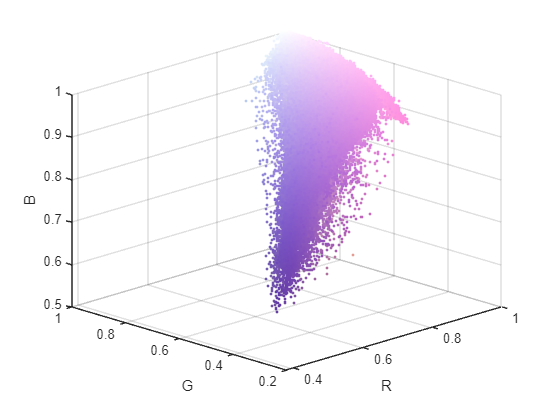

dt.scatter3('RGB');

## Save the outputs

disp('Saving data to files');

% CIE coordinates
XYZ_array = dt.XYZ;
save([pwd '\output\' sample_name '\CIE_Coord\XYZ_array'],'XYZ_array');
CovXYZ_array = dt.CovXYZ;
save([pwd '\output\' sample_name '\CIE_Coord\CovXYZ_array'],'CovXYZ_array');
LAB_array = dt.LAB;
save([pwd '\output\' sample_name '\CIE_Coord\LAB_array'],'LAB_array');
CovLAB_array = dt.CovLAB;
save([pwd '\output\' sample_name '\CIE_Coord\CovLAB_array'],'CovLAB_array');

% sRGB and Tiff
rgb = dt.rgb;
save([pwd '\output\' sample_name '\RGB\rgb'],'rgb');
imwrite(im ,[pwd '\output\' sample_name '\RGB\truth.tif']);